# **Asignación de Transformadas Discretas de Fourier**

#### Calentamiento

- Considere las siguientes señales

$y_1 \left(t\right)=3\cos \left(\omega t\right)+5\cos \left(5\omega t\right)+8\cos \left(7\omega t\right)$ y $y_2 \left(t\right)=3\sin \left(\omega t\right)+2\sin \left(3\omega t\right)+3\sin \left(8\omega t\right)$

a) Implemente en cada caso la transformada analítica y discreta de Fourier. Compárelas.

b) Mustre para cuales casos recupera una transformada real o imaginaria.

Caso 1 $y_1 \left(t\right)=3\cos \left(\omega t\right)+5\cos \left(5\omega t\right)+8\cos \left(7\omega t\right)$

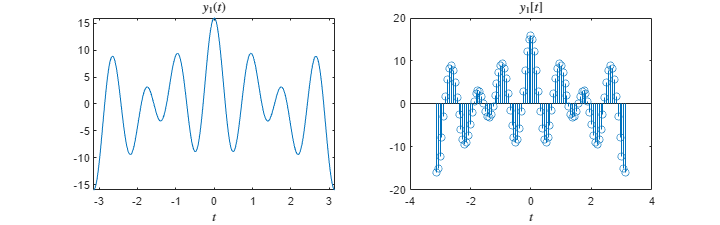

clear;
clc;

T = 2*pi;                   % Período
medT = T/2;                 % Madio período
Amp = 1;                    % Amplitud
Nterm = 10;                 % Número de términos en la serie de fourier
kMax = floor(2*Nterm*pi/T); % máxima frecuencia


y = @(t) 3*cos(1*t) + 5*cos(5*1*t) + 8*cos(7*1*t);

figure();
x0=0;
y0=0;
width=800;
height=250;
set(gcf,'position',[x0,y0,width,height])
    
subplot(1, 2, 1);
fplot(y, [-pi pi]);
xlabel("$t$", "Interpreter","latex");
title("$y_1(t)$", "Interpreter","latex")

subplot(1, 2, 2);

intervals = 0.02;
t_axis = -1:intervals:1;
t_axis = t_axis*pi;

y_eval = double(y(t_axis));
stem(t_axis, y_eval);
xlabel("$t$", "Interpreter","latex");
title("$y_1[t]$", "Interpreter","latex");

syms t k

y_sym =  3*cos(1*t) + 5*cos(5*1*t) + 8*cos(7*1*t);
Fy(k) = fourier(y_sym, k);

delta = @(x) 1.*(x == 0);
display(Fy);

$$Fy(k) = 3\,\pi \,\left(\delta (k-1)+\delta (k+1)\right)+5\,\pi \,\left(\delta (k-5)+\delta (k+5)\right)+8\,\pi \,\left(\delta (k-7)+\delta (k+7)\right)$$

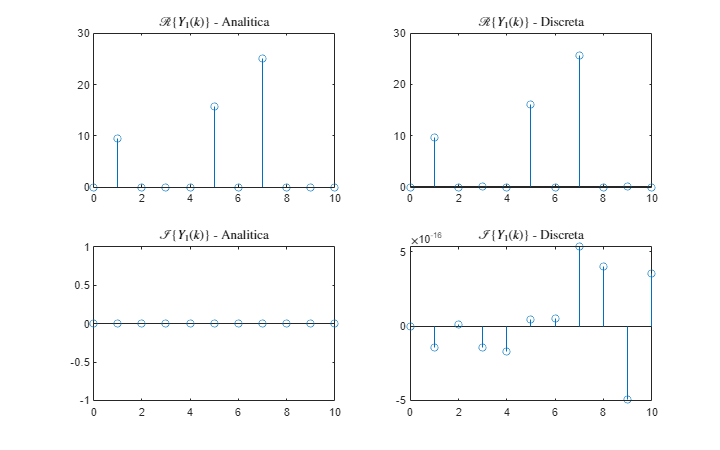

Fy = @(x) 3*pi*( delta(x-1) +  delta(x+1) ) + ...
          5*pi*( delta(x-5) +  delta(x+5) ) + ...
          8*pi*( delta(x-7) +  delta(x+7) );

k_axis = 0:1:Nterm;

Fy_eval =  Fy(k_axis);

figure();
x0=0;
y0=0;
width=800;
height=500;
set(gcf,'position',[x0,y0,width,height])


subplot(2,2, 1);
stem(k_axis, real(Fy_eval));
title("$\mathcal{R}\{ Y_1(k) \}$ - Analitica", "Interpreter","latex");

subplot(2,2, 3);
stem(k_axis, imag(Fy_eval));
title("$\mathcal{I}\{ Y_1(k) \}$ - Analitica", "Interpreter","latex");

N = 1000;

C = custom_dft(y, T, N, Nterm);

subplot(2,2, 2);

stem(k_axis, real(C));
title("$\mathcal{R}\{ Y_1(k) \}$ - Discreta", "Interpreter","latex");

subplot(2,2, 4);

stem(k_axis, imag(C));
title("$\mathcal{I}\{ Y_1(k) \}$ - Discreta", "Interpreter","latex");

**Comentarios:  **Como podemos intuir al analizar los componentes que conformar la señal $y_1 \left(t\right)$, dicha serie al estar compuesta por funciones coseno $\cos \left(x\right)$ centradas en el origen,  es decir unicamente funciones par, esto se traducira en una respuesta en la frecuencia de la señal con unicamente componentes reales, como se puede observar al realizar la transformada analitica de la señal, la cual da como resultado los pares de deltas de diract ubicados en los puntos de caracterizan las frecuencias que componena cada termino coseno. Sin embargo, al comparlo con la transformada discreta de Fourier, encontramos un comportamiento similar en el caso de la parte real, pero ademas hay presencia de coeficiente en la parte imaginaria,  lo cual puede deverse a errores de precisión numerica dado que la presencia de dichos coeficientes en comparación a su parte real es depreciable.

Caso 2 $y_2 \left(t\right)=3\sin \left(\omega t\right)+2\sin \left(3\omega t\right)+3\sin \left(8\omega t\right)$

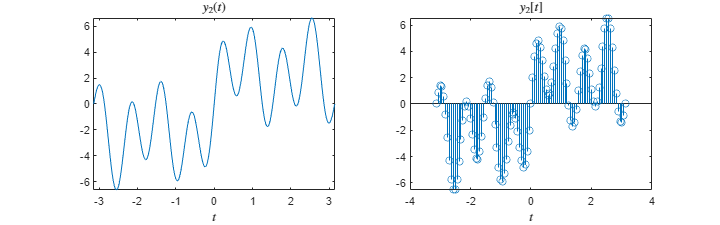

clear;
clc;

T = 2*pi;                   % Período
medT = T/2;                 % Madio período
Amp = 1;                    % Amplitud
Nterm = 10;                 % Número de términos en la serie de fourier
kMax = floor(2*Nterm*pi/T); % máxima frecuencia

y = @(t) 3*sin(1*t) + 2*sin(3*1*t) + 3*sin(8*1*t);

figure();
x0=0;
y0=0;
width=800;
height=250;
set(gcf,'position',[x0,y0,width,height])
    
subplot(1, 2, 1);
fplot(y, [-pi pi]);
xlabel("$t$", "Interpreter","latex");
title("$y_2(t)$", "Interpreter","latex")

subplot(1, 2, 2);

intervals = 0.02;
t_axis = -1:intervals:1;
t_axis = t_axis*pi;

y_eval = double(y(t_axis));
stem(t_axis, y_eval);
xlabel("$t$", "Interpreter","latex");
title("$y_2[t]$", "Interpreter","latex");

syms t k

y_sym =  3*sin(1*t) + 2*sin(3*1*t) + 3*sin(8*1*t);
Fy(k) = fourier(y_sym, k);

delta = @(x) 1.*(x == 0);
display(Fy);

$$Fy(k) = -3\,\pi \,\left(\delta (k-1)-\delta (k+1)\right)\,\mathrm{i}-2\,\pi \,\left(\delta (k-3)-\delta (k+3)\right)\,\mathrm{i}-3\,\pi \,\left(\delta (k-8)-\delta (k+8)\right)\,\mathrm{i}$$

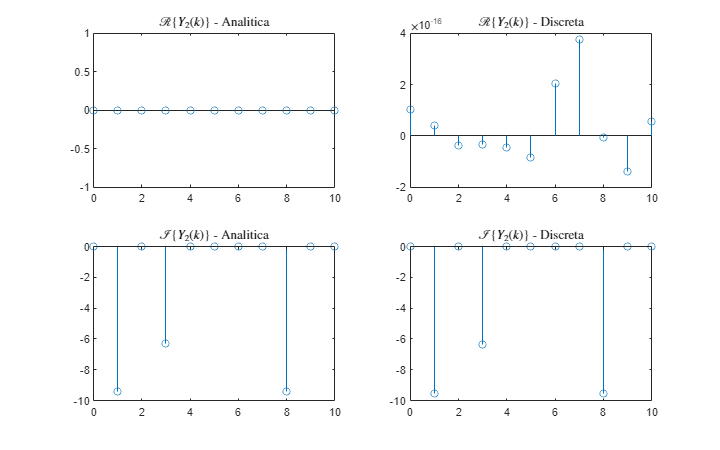

Fy = @(x) -3*pi*( delta(x-1) +  delta(x+1) ).*1j + ...
          -2*pi*( delta(x-3) +  delta(x+3) ).*1j + ...
          -3*pi*( delta(x-8) +  delta(x+8) ).*1j;

k_axis = 0:1:Nterm;

Fy_eval =  Fy(k_axis);

figure();
x0=0;
y0=0;
width=800;
height=500;
set(gcf,'position',[x0,y0,width,height])


subplot(2,2, 1);
stem(k_axis, real(Fy_eval));
title("$\mathcal{R}\{ Y_2(k) \}$ - Analitica", "Interpreter","latex");

subplot(2,2, 3);
stem(k_axis, imag(Fy_eval));
title("$\mathcal{I}\{ Y_2(k) \}$ - Analitica", "Interpreter","latex");

N = 1000;
h = T/N;

C = custom_dft(y, T, N, Nterm);

subplot(2,2, 2);

stem(k_axis, real(C));
title("$\mathcal{R}\{ Y_2(k) \}$ - Discreta", "Interpreter","latex");

subplot(2,2, 4);

stem(k_axis, imag(C));
title("$\mathcal{I}\{ Y_2(k) \}$ - Discreta", "Interpreter","latex");

**Comentarios:  **Como podemos intuir al analizar los componentes que conformar la señal $y_2 \left(t\right)$, dicha serie al estar compuesta por funciones seno $\sin \left(x\right)$ centradas en el origen, es decir unicamente funciones impares, esto se traducira en una respuesta en la frecuencia de la señal con unicamente componentes imaginarias, como se puede observar al realizarla transformada analitica de la señal, la cual da como resultado los pares de deltas de diract ubicados en los puntos de caracterizan las frecuencias que componena cada termino seno. Sin embargo, al comparlo con la transformada discreta de Fourier, encontramos un comportamiento similar en el caso de la parte imaginaria, pero ademas hay presencia de coeficiente en la parte real, lo cual puede deverse a errores de precisión numerica dado que la presencia de dichos coeficientes en comparación a su parte imaginaria es depreciable.

c) Encuentre las distintas componentes para el espectro de potencias y muestre que las frecuencias tienen los valores esperados (no sólo las proporciones)

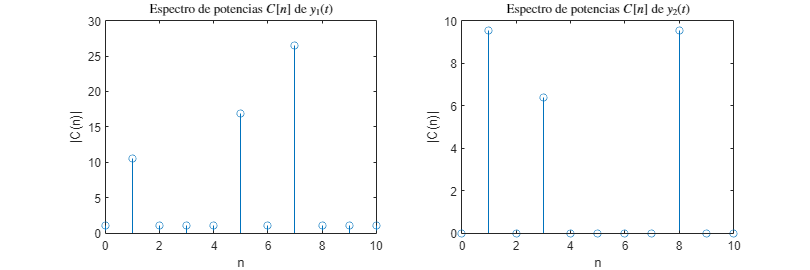

y1 = @(t) 3*cos(1*t) + 5*cos(5*1*t) + 8*cos(7*1*t);
y2 = @(t) 3*sin(1*t) + 2*sin(3*1*t) + 3*sin(8*1*t);

T = 2*pi;
Nterm = 10;
N = 100;
  

figure();
x0=0;
y0=0;
width=900;
height=300;
set(gcf,'position',[x0,y0,width,height])

subplot(1, 2, 1);

C = custom_coef(y1, T, N, Nterm);
stem(0:Nterm, abs(C));
title("Espectro de potencias $C[n]$ de $y_1(t)$", "Interpreter","latex");
xlabel("n");
ylabel("|C(n)|")

subplot(1, 2, 2);

C = custom_coef(y2, T, N, Nterm);
stem(0:Nterm, abs(C));
title("Espectro de potencias $C[n]$ de $y_2(t)$", "Interpreter","latex");
xlabel("n");
ylabel("|C(n)|")

d) Experimente los efectos de elegir diferentes valores de tamaño de paso $h$ y de ampliar el período de medicion $T=\textrm{Nh}$

Diferentes tamaños $h$

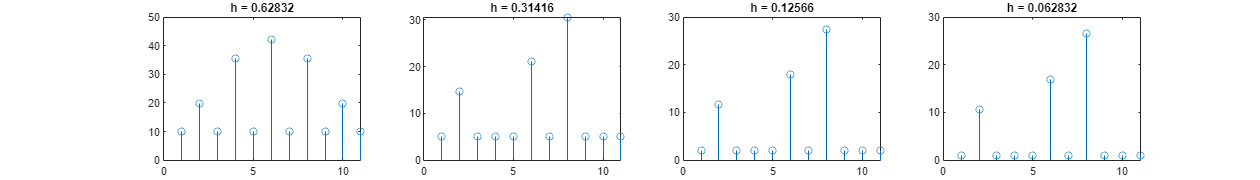

clear;
clc;

y = @(t) 3*cos(1*t) + 5*cos(5*1*t) + 8*cos(7*1*t);

T = 2*pi;  
Nterm = 10;

hs = [10 20 50 100];

figure();

x0=0;
y0=0;
width=1400;
height=200;
set(gcf,'position',[x0,y0,width,height])


for i=1:length(hs)

    subplot(1, length(hs), i)
    N = hs(i);
    C = custom_dft(y, T, N, Nterm);
    stem(abs(C));
    title("h = " + num2str(T/N));

end

**Comentarios: **Como podemos observar, conforma disminuimos el tamaño del paso $h$, se puede observar una mejor aproximación a resultado obtenido mendiante la transformada analitica de Fourier, dado que estamos aumentando las cantidad de terminos involucrados en la sumatoria y por ende aproximamos mejor al resultado obtenido mendiate la integración. 

Diferentes periodos de medición $T$

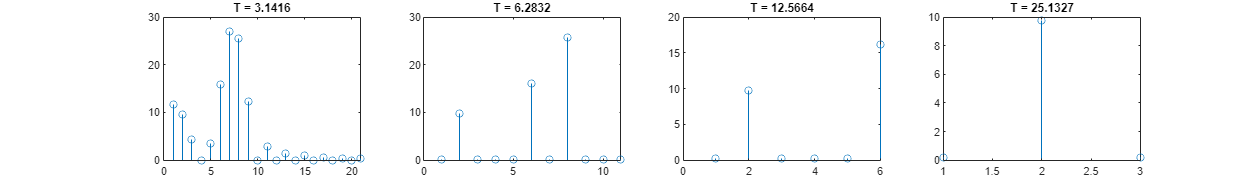

clear;
clc;

y = @(t) 3*cos(1*t) + 5*cos(5*1*t) + 8*cos(7*1*t);

Nterm = 10;

Ts = [1 2 4 8];
Ts = Ts*pi;

N = 500;

figure();

x0=0;
y0=0;
width=1400;
height=200;
set(gcf,'position',[x0,y0,width,height])


for i=1:length(Ts)

    subplot(1, length(Ts), i)
    T = Ts(i);
    C = custom_dft(y, T, N, Nterm);
    stem(abs(C));
    title("T = " + num2str(T));

end

**Comentarios: **Como podemos observar, conforme aumentamos el periodo de medición, vemos como disminuye la cantidad de terminos que podemos calcular en la expasión de la serie de fourier, permitiendo solo estimar las frecuencias mas bajas de la señal $y_1 \left(t\right)$, cuando el periodo de medición es propocional a la maxima frecuencia de la señal, obtenemos una buena aproximación de la transformada analitica. En el caso en el que el periodo de medición es menor al periodo de la señal $y_1 \left(t\right)$, estamos realizando una estimación con mayor variedad en la expación de la serie de fourier.

2. Considere ahora la siguiente señal


$$y\left(t_i \right)=\frac{10}{10-9\sin \left(t_i \right)}+\alpha \left(3R_i -1\right)\;\textrm{con}\;0\le R_i \le 1$$


a) Grafique su señal ruidosa, su transformada de fourier (analítica) y su espectro de potencia.

syms t k

y_sym =  10/(10 - 9*sin(t));
Fy(k) = fourier(y_sym, k);

display(Fy);

$$Fy(k) = -10\,\mathrm{fourier}\left(\frac{1}{9\,\sin\left(t\right)-10},t,k\right)$$

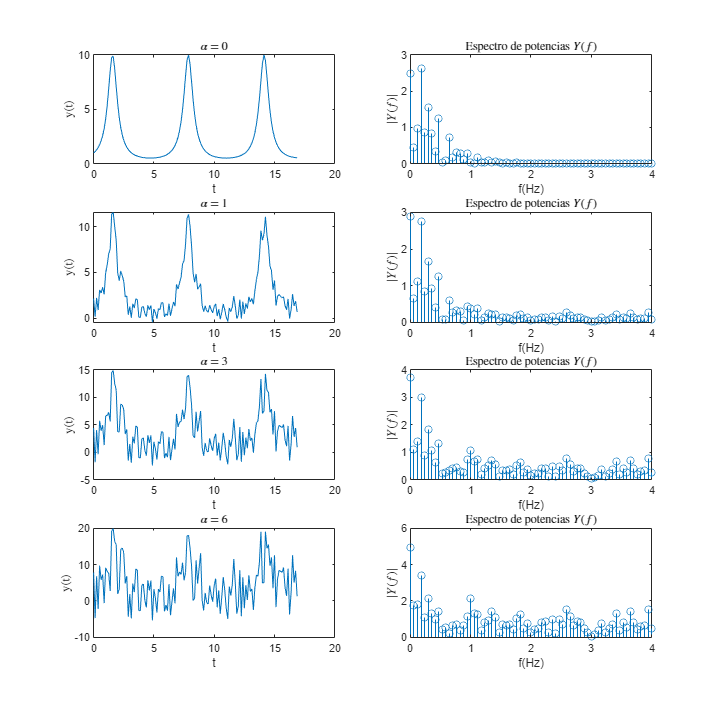



Fs = 8;                % Sampling frequency                    
T = 1/Fs;              % Sampling period       
L = Fs*17;             % Length of signal
t = (0:L-1)*T;         % Time vector
N = length(t);
R = rand(1, N);
f = Fs*(0:(L/2))/L;


y = @(alpha)  10./( 10 - 9*sin(t)) + alpha.*(3.*R - 1);


figure();
x0=0;
y0=0;
width=800;
height=800;
set(gcf,'position',[x0,y0,width,height])

alphas = [0 1 3 6];
n_plots = length(alphas);


for i = 1:n_plots
    
    alpha = alphas(i);
    y_seq = y(alpha);


    subplot(n_plots,2,i*2 - 1);
    plot(t, y_seq);
    title("$\alpha$ = " + num2str(alpha), "Interpreter","latex");
    xlabel("t");
    ylabel("y(t)", "Interpreter","latex");


    subplot(n_plots,2, i*2);
    
    Y = fft(y_seq);    
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);      
    stem(f,  P1);
    title("Espectro de potencias $Y(f)$", "Interpreter","latex");
    xlabel("f(Hz)")
    ylabel("$|Y(f)|$", "Interpreter","latex");

end

Calcule la función de autocorrelación $A\left(\tau \right)$ y su transformada de Fourier $A\left(\omega \right)$

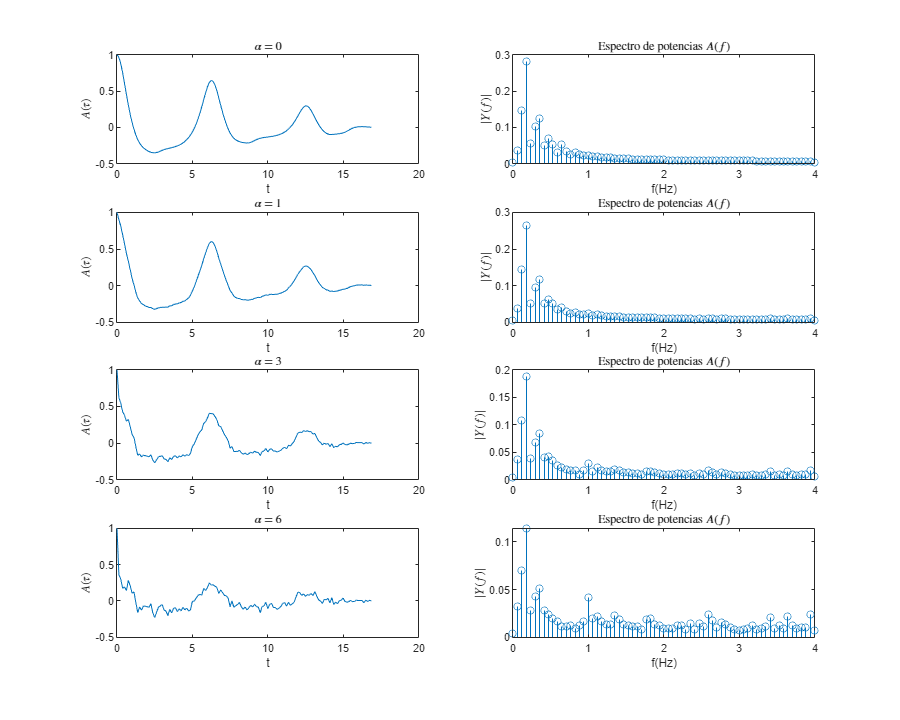

y = @(alpha)  10./( 10 - 9*sin(t)) + alpha.*(3.*R - 1);


figure();
x0=0;
y0=0;
width=1000;
height=800;
set(gcf,'position',[x0,y0,width,height])

alphas = [0 1 3 6];
n_plots = length(alphas);


for i = 1:n_plots
    
    alpha = alphas(i);
    y_seq = y(alpha);
    y_seq = autocorr(y_seq, NumLags=L-1);

    subplot(n_plots,2,i*2 - 1);
    plot(t, y_seq);
    title("$\alpha$ = " + num2str(alpha), "Interpreter","latex");
    xlabel("t");
    ylabel("$A(\tau)$", "Interpreter","latex");


    subplot(n_plots,2, i*2);
    
    Y = fft(y_seq);    
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);      
    stem(f,  P1);
    title("Espectro de potencias $A(f)$", "Interpreter","latex");
    xlabel("f(Hz)")
    ylabel("$|Y(f)|$", "Interpreter","latex");

end

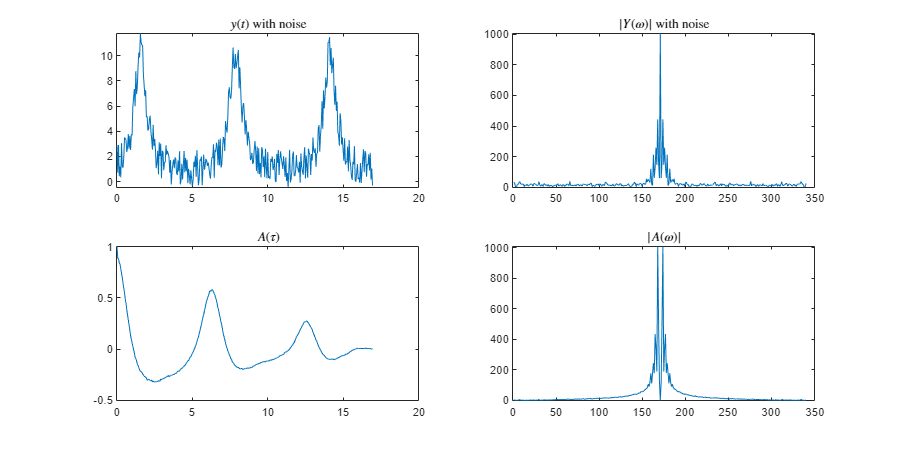

Fs = 20;                % Sampling frequency                    
T = 1/Fs;              % Sampling period       
L = Fs*17;             % Length of signal
t = (0:L-1)*T;         % Time vector
N = length(t);
R = rand(1, N);

y = @(alpha)  10./( 10 - 9*sin(t)) + alpha.*(3.*R - 1);

alpha = 1;
y_eval = y(alpha);
Y = fftshift(  fft(y_eval) );

At = autocorr(y_eval, NumLags=N-1);
Af =  fftshift(  fft(At) ) ;

scale = max( Y );

figure();
x0=0;
y0=0;
width=1000;
height=500;
set(gcf,'position',[x0,y0,width,height])


subplot(2, 2, 1);
plot(t, y_eval);
title("$y(t)$ with noise", "Interpreter","latex");

subplot(2, 2, 2);
plot( abs(Y) );
title("$|Y(\omega)|$ with noise", "Interpreter","latex");

subplot(2, 2, 3);
plot(t, At);
title("$A(\tau)$", "Interpreter","latex");

MAf = Af;
MAf = MAf - min(MAf);
MAf = MAf ./ max(MAf);
MAf = MAf*scale;

subplot(2, 2, 4);
plot( abs(MAf));
title("$|A(\omega)|$", "Interpreter","latex");

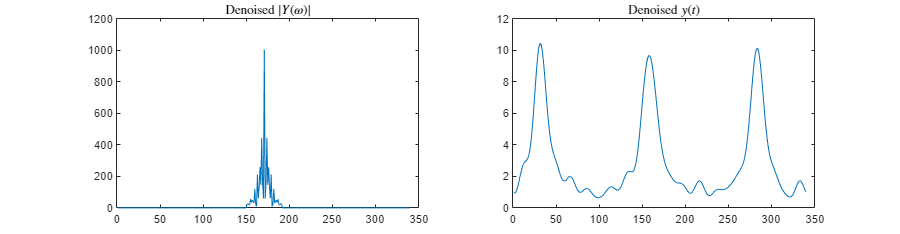

% figure();
p = 0.10;
Afs = sort(abs(Af), 'descend');
% plot(Afs);
ind = round(p*N);
threshold = Afs(ind);

indxs = Af < threshold;

denoised_Y =  Y;
% denoised_Y(indxs) = 0;
w = 21;
midF = 170;

denoised_Y(1:midF-w+1)= 0;
denoised_Y(midF+w+1:end) = 0;

y_recons  = ifft( fftshift( denoised_Y ) );


figure();
x0=0;
y0=0;
width=1000;
height=260;
set(gcf,'position',[x0,y0,width,height])

subplot(1, 2, 1);
plot(  abs(denoised_Y) );
title("Denoised $|Y(\omega)|$", "Interpreter","latex");

subplot(1, 2, 2);
plot(  y_recons );
title("Denoised $y(t)$", "Interpreter","latex");